# Electrolyzer Stack model

clear all; clc; close all;

## Import the data

to_import = ["eff1","eff2","eff3","eff4","eff5"];

m = struct("control",[])

m = struct with fields:
    control: []


m.time = [];
m.I_stack = [];
m.U_stack = [];
m.T_in = [];
m.T_out = [];
m.tankP = [];
m.cooling = [];
m.Ph2o = [];
m.Po2 = [];
m.Ph2 = [];
for c = 1:length(to_import)
    tdms = TDMS_getStruct(convertStringsToChars(to_import(c)+ ".tdms"))
    measurements = tdms.Group1;
    m(:).control = [m.control measurements.Control.data];
    m(:).time = [m.time measurements.Time.data];
    m(:).I_stack  =[m.I_stack measurements.I_Stack.data];
    m(:).U_stack = [m.U_stack measurements.U_Stack.data];
    m(:).T_in = [m.T_in measurements.O2_T_In.data];
    m(:).T_out = [m.T_out measurements.O2_T_Out.data];
    m(:).tankP = [m.tankP measurements.H2_PrProd.data];
    m(:).cooling = [m.cooling measurements.Cooling_.data];
    m(:).Ph2o = [m.Ph2o measurements.H2O_PrStackIn.data];
    m(:).Po2 = [m.Po2 measurements.O2_PrStackOut.data];
    m(:).Ph2 = [m.Ph2 measurements.H2_PrSys.data];
    fprintf(c + ".tdms")
end

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


1.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


2.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


3.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


4.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


5.tdms

m(:).T = (m.T_in+m.T_out)./2;               %get the average stack temperature

### Create the experiment slices (indexing variables) to use further in the script

firstrun_idx = m.time>1000 & m.time<6300;   %slice for the the first experiment
all_run = m.time>2000 & m.time<16000 ;       %slice for the full experiment
automode_idx = m.control == 2;              %slice for the automatic mode
automode_times = m.time(m.control == 2);    %timestamps for the automatic mode
validsamples = m.I_stack > 10 & m.time>2000 & m.time<16500; 

### Plot the full experiment

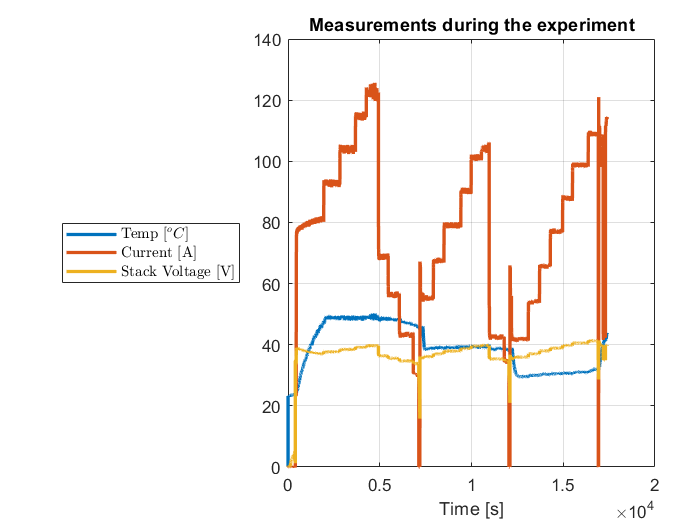

figure;
plot(m.time,[m.T;m.I_stack;m.U_stack],"LineWidth",2)
xlabel("Time [s]")

hold on
%xline(min(automode_times),"r")
%xline(max(automode_times),"g")
ylim([0 140])
hold off
grid on
legend("Temp [$^oC$]","Current [A]","Stack Voltage [V]","location","westoutside","interpreter","latex")%,"Automatic mode")
title("Measurements during the experiment")

## Useful Constants

EH2 = 285840;           %[J/mol] internal energy of hydrogen
F = 96485;              %Faraday Constant
R = 8.3145;             %ideal gas constant [J/K/mol]
ncell = 20;             %number of cells in the stack
KtoC = 273.15;          %Kelvin To Celcius conversion constant
V0_theory_datasheet = 1.48;     %reversible stack potential
Tamb = 21;              %^oC
Vtank = 1.6;            %m^3
bar_to_Pa = 100000;     % 1 bar = 100000 Pa

## Reversible potential

#### Nominal values are the average pressures

PH2 = mean(m.Ph2(firstrun_idx))

PH2 = 31.0654

PO2 = mean(m.Po2(firstrun_idx))

PO2 = 3.8468

PH2O = mean(m.Ph2o(firstrun_idx))

PH2O = 4.6387

#### H2O pressure histogram

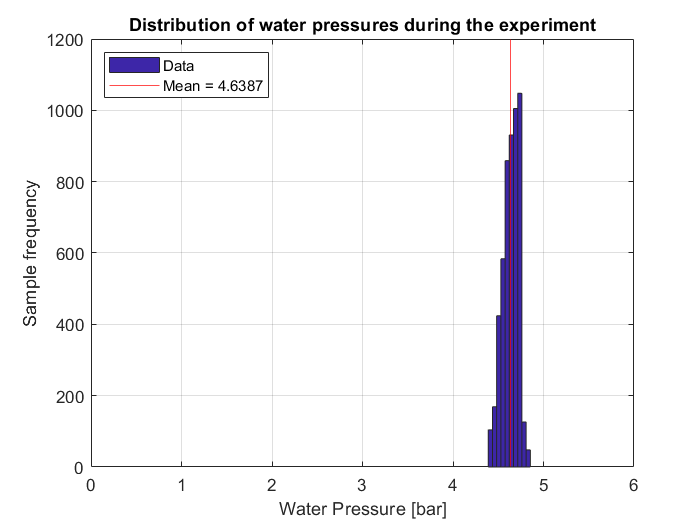

figure;
hist(m.Ph2o(firstrun_idx),10,"Displayname","Data");
hold on
xline(PH2O,"r","displayname","Mean")
hold off
xlim([0,6])
grid on
xlabel("Water Pressure [bar]")
ylabel("Sample frequency")
title("Distribution of water pressures during the experiment")
legend("Data", "Mean = " + num2str(PH2O),"Location","northwest")

#### O2 pressure histogram

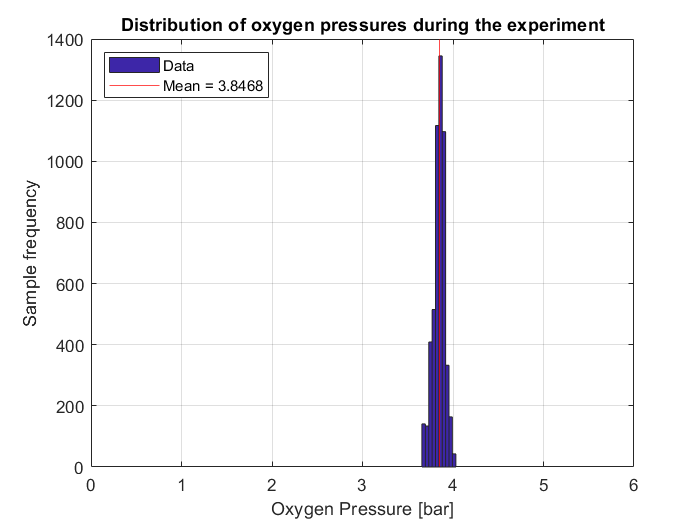

figure;
hist(m.Po2(firstrun_idx),10);
xlim([0,6])
grid on
hold on
xline(PO2,"r")
hold off
legend("location", "best")
xlabel("Oxygen Pressure [bar]")
ylabel("Sample frequency")
title("Distribution of oxygen pressures during the experiment")
legend("Data","Mean = " + num2str(PO2),"Location","northwest")

#### H2 pressure histogram

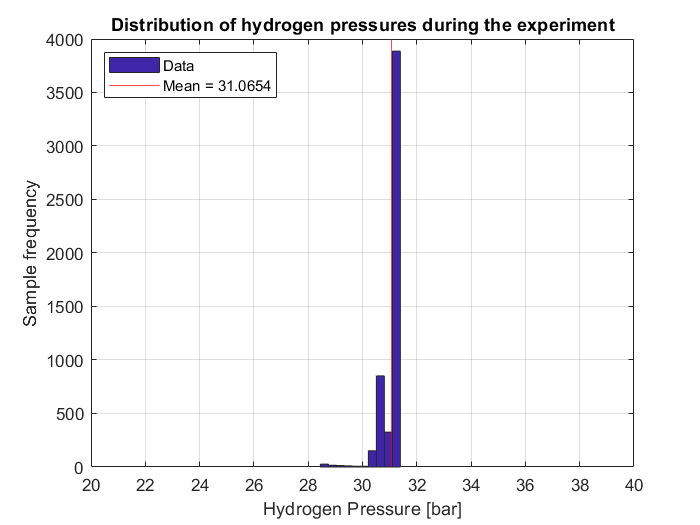

figure;
hist(m.Ph2(firstrun_idx),10,"Displayname","Data");
hold on
xline(PH2,"r")
hold off
xlim([20,40])
grid on
xlabel("Hydrogen Pressure [bar]")
ylabel("Sample frequency")
title("Distribution of hydrogen pressures during the experiment")
legend("Data", "Mean = " + num2str(PH2),"Location","northwest")

#### Find the reversible voltage expression

syms T_stack;
V0_hydrogen = EH2/(2*F)

V0_hydrogen = 1.4813

V0_theory_datasheet

V0_theory_datasheet = 1.4800

sympref('FloatingPointOutput',true);
Vrev = V0_hydrogen + T_stack*R/(2*F)*log(PH2*sqrt(PO2)/PH2O)

$$Vrev = 1.1096e-04\,T_{\mathrm{stack}}+1.4813$$

## Diffusion overpotential

Nothing to code.

## Activation overpotential

Nothing to code.

## Ohmic overpotential

#### Plot for different Epro

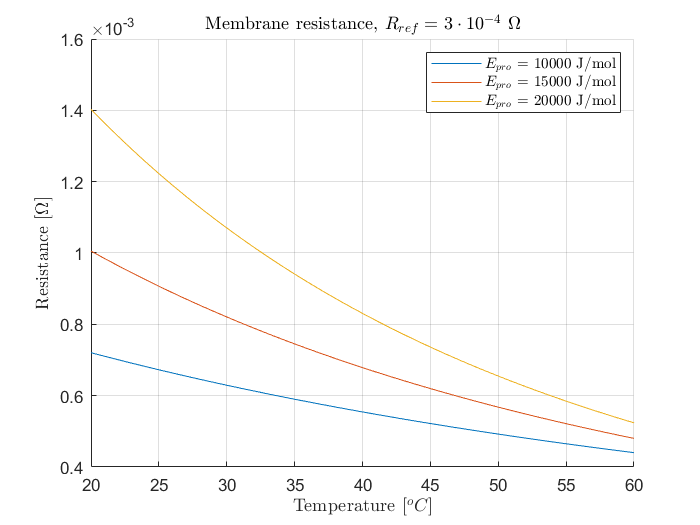

Epro = [10e3, 15e3,20e3];
Rref = 3.7e-4;
Tcell = [20:60] + KtoC;
figure
for Ep = Epro
    hold on
    plot(Tcell-KtoC, Rref.*exp(Ep./R.*(1./Tcell-1./350)),"DisplayName","$E_{pro}$ = " + num2str(Ep) + "~J/mol");
    hold off
end
grid on
legend("interpreter","latex")
xlabel("Temperature $[^oC]$","Interpreter","latex")
ylabel("Resistance [$\mathrm{\Omega}$]","Interpreter","latex")
title("Membrane resistance, $R_{ref} = 3 \cdot 10^{-4} \mathrm{~\Omega}$","Interpreter","latex")

#### Plot for different Rref

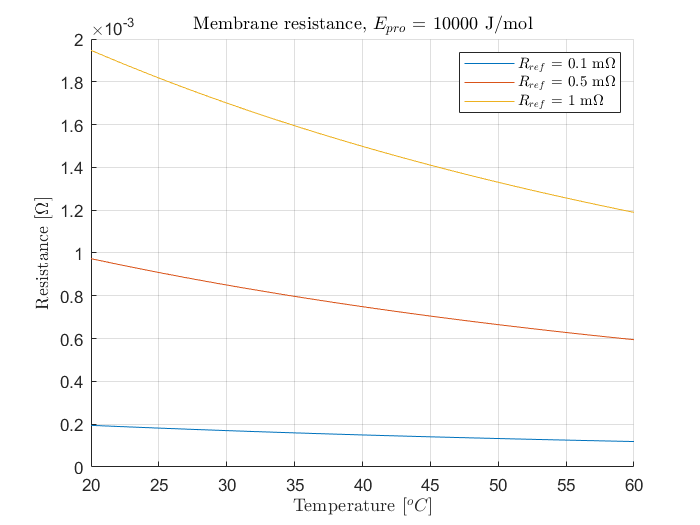

Epro = 10e3;
Rref = [1e-4,5e-4,10e-4];
Tref = KtoC + 50;
Tcell = [20:60] + KtoC;
figure
for RR = Rref
    hold on
    plot(Tcell-KtoC, RR.*exp(Epro./R.*(1./Tcell-1./350)),"DisplayName","$R_{ref}$ = " + num2str(RR*1000) + "$ \mathrm{~m\Omega}$");
    hold off
end
grid on
xlabel("Temperature $[^oC]$","Interpreter","latex")
ylabel("Resistance [$\mathrm{\Omega}$]","Interpreter","latex")
legend("interpreter","latex")
title("Membrane resistance, $E_{pro}$ = 10000 J/mol","Interpreter","latex")

## Preprocessing & cleanup

#### Plot raw data

figure;
scatter3(m.T,m.I_stack,m.U_stack/20,".")
title("Raw data","Interpreter","latex")
xlabel("Temperature $[^oC]$","Interpreter","latex")
ylabel("Stack Current [A]","Interpreter","latex")
zlabel("Single cell voltage [V]","Interpreter","latex")
%xlim([0 50])
%ylim([0 120])
zlim([0,3])

### Cleanup the data

Take samples with I > 10A and during steady operation.

slice = m.I_stack > 10 & m.time>1000 & m.time<169017;
mm.I_stack = m.I_stack(slice);
mm.U_stack = m.U_stack(slice);
mm.T = m.T(slice);

#### Perform cleanup with tolerances

itol = 1;
temptol = 1;

cleandata.I_stack  = [];
cleandata.U_stack  = [];
cleandata.T  = [];
for j = 20:itol:120
    for k = 20:temptol:50
        to_avg = mm.I_stack < j+itol & mm.I_stack > j & ...
            mm.T < k+temptol & mm.T > k;
        if sum(to_avg) > 100
            cleandata(:).I_stack  =[cleandata.I_stack ones(1,sum(to_avg)).*mean(mm.I_stack(to_avg))];
            cleandata(:).U_stack = [cleandata.U_stack ones(1,sum(to_avg)).*mean(mm.U_stack(to_avg))];
            cleandata(:).T = [cleandata.T ones(1,sum(to_avg)).*mean(mm.T(to_avg))];
%             cleandata(:).I_stack  =[cleandata.I_stack mm.I_stack(to_avg)];%ones(1,sum(to_avg)).*mean(mm.I_stack(to_avg))];
%             cleandata(:).U_stack = [cleandata.U_stack mm.U_stack(to_avg)];%ones(1,sum(to_avg)).*mean(mm.U_stack(to_avg))];
%             cleandata(:).T = [cleandata.T mm.T(to_avg)];%ones(1,sum(to_avg)).*mean(mm.T(to_avg))];
        end
    end
end
cleandata.P = cleandata.U_stack.*cleandata.I_stack;

#### Plot the cleaned-up data.

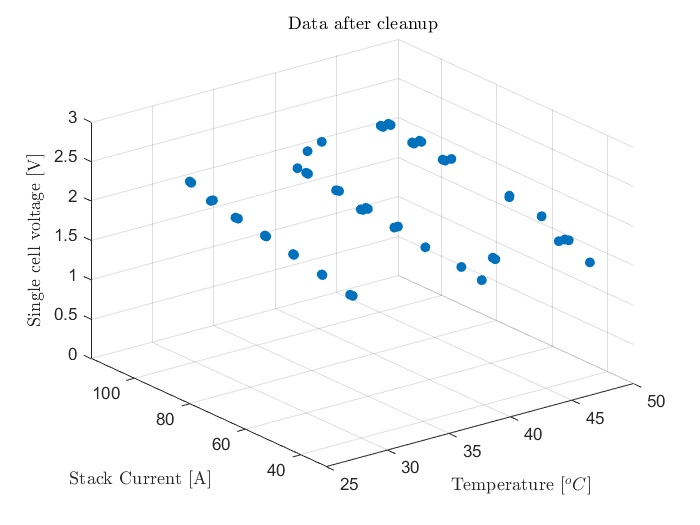

close all;
figure;
scatter3(cleandata.T,cleandata.I_stack,cleandata.U_stack/20,"filled")
title("Data after cleanup","Interpreter","latex")
xlabel("Temperature $[^oC]$","Interpreter","latex")
ylabel("Stack Current [A]","Interpreter","latex")
zlabel("Single cell voltage [V]","Interpreter","latex")
zlim([0,3])

## OLS Fitting

#### Choose data to fit

I_stack = cleandata.I_stack;
U_cell = cleandata.U_stack./ncell;
T = cleandata.T + KtoC;

#### Manually-calculate OLS

%Fit on cleaned-up samples
Y_train = (U_cell - 1.4813 - 1.11e-4.*T)';
X_train = [T; sqrt(I_stack); T.*sqrt(I_stack); I_stack; T.*I_stack]'; 
format shortE
beta_ols = (X_train'*X_train)\(X_train'*Y_train);
parameter_names = ["a","b","c","d","h"];
fitting_results = array2table(beta_ols,"RowNames",parameter_names);
disp(fitting_results)

          beta_ols  
         ___________

    a     2.3506e-04
    b     1.6688e-01
    c    -5.2077e-04
    d     9.9207e-03
    h    -2.0764e-05



format short
%Test on all samples
validsamples = validsamples & automode_idx;
m(:).T_in_K = m.T+KtoC;
Y_test = (m.U_stack(validsamples)./ncell - 1.4813 - 1.11e-4.*m.T_in_K(validsamples))';
X_test = [m.T_in_K(validsamples); sqrt(m.I_stack(validsamples)); m.T_in_K(validsamples).*sqrt(m.I_stack(validsamples)); m.I_stack(validsamples); m.T_in_K(validsamples).*m.I_stack(validsamples)]'; 

#### Test the fitting on the fitting samples

epsilon_train = Y_train-X_train*beta_ols;
RMS_error_on_training = rms(epsilon_train)

RMS_error_on_training = 0.0032

R2_on_training = 1 - RMS_error_on_training^2/var(U_cell)

R2_on_training = 0.9988

#### Test the fitting on all samples

epsilon_test = Y_test-X_test*beta_ols;
RMS_error_on_test = rms(epsilon_test)

RMS_error_on_test = 0.0039

R2_on_test = 1 - RMS_error_on_test.^2/var(m.U_stack(validsamples)./ncell)

R2_on_test = 0.9982

#### Plot the absolute errors

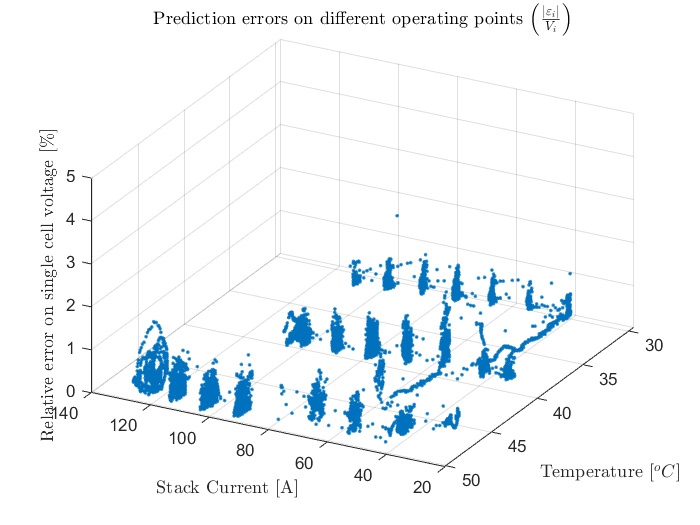

figure;
plot3(m.I_stack(validsamples),m.T_in_K(validsamples)-KtoC, abs(epsilon_test).*100,".")
ylabel("Temperature $[^oC]$","Interpreter","latex")
xlabel("Stack Current [A]","Interpreter","latex")
zlabel("Relative error on single cell voltage [\%]","Interpreter","latex")
grid on
title("Prediction errors on different operating points $\left(\frac{|\varepsilon_i|}{V_i}\right)$","Interpreter","latex")
zlim([0, 5])
view([-151.8867 36.2767])

#### Use MATLAB built-in fitting & print the results (should be the same)

close all;
[fittedmodel,gof] = model_fit(I_stack,T,U_cell);
gof

gof = struct with fields:
           sse: 0.1241
       rsquare: 0.9988
           dfe: 11947
    adjrsquare: 0.9988
          rmse: 0.0032


fittedmodel

     General model:
     fittedmodel(I,T) = 1.4813+1.11e-4*T+a*T+(b+c*T)*sqrt(I)+(d+h*T)*I
     Coefficients (with 95% confidence bounds):
       a =   0.0002351  (0.0002281, 0.000242)
       b =      0.1669  (0.1648, 0.1689)
       c =  -0.0005208  (-0.0005275, -0.000514)
       d =    0.009921  (0.009697, 0.01014)
       h =  -2.076e-05  (-2.148e-05, -2.005e-05)



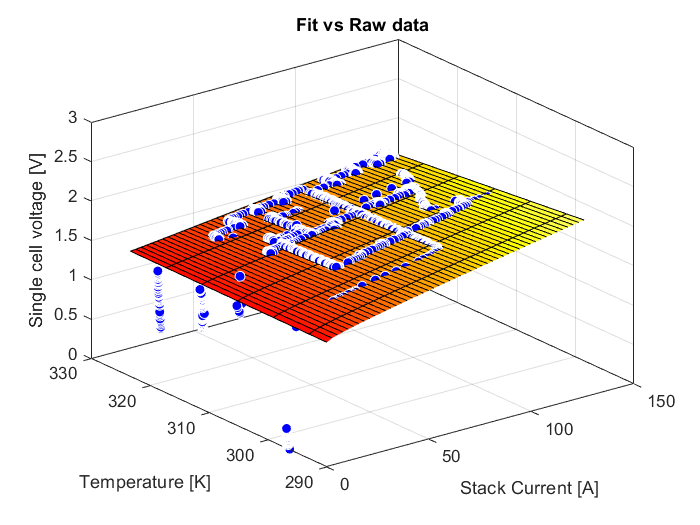

figure;
plt = plot(fittedmodel, [[m.I_stack';1] [m.T'+KtoC;20]], [(m.U_stack./ncell)';1.5]);
colormap("hot")
caxis([1 2.5])
title("Fit vs Raw data")
ylabel("Temperature [K]")
xlabel("Stack Current [A]")
zlabel("Single cell voltage [V]")
ylim([290 330])
xlim([0 150])
zlim([0 3])

## Model verification 

#### Setup current interval to verify the model on

minI = 10

minI = 10

maxI = 150

maxI = 150

current = minI:1:maxI;

#### Extract the points around fixed temperatures

tempslice40 = cleandata.T > 38.5 & cleandata.T<41.5 & cleandata.I_stack>minI;
tempslice30 = cleandata.T > 28.5 & cleandata.T<31.5 & cleandata.I_stack>minI;
tempslice50 = cleandata.T > 47   & cleandata.T<50   & cleandata.I_stack > minI;

#### Plot model vs. measurements at different temperatures

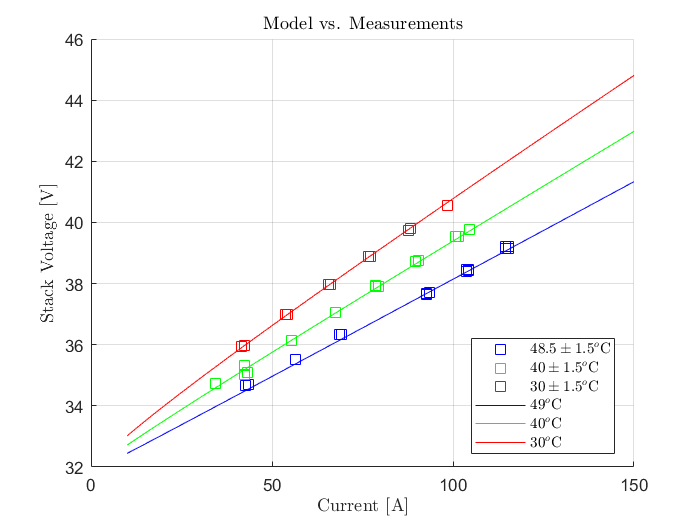

figure;
hold on
plot(cleandata.I_stack(tempslice50),cleandata.U_stack(tempslice50),"bs","MarkerSize",8)
plot(cleandata.I_stack(tempslice40),cleandata.U_stack(tempslice40),"gs","MarkerSize",8)
plot(cleandata.I_stack(tempslice30),cleandata.U_stack(tempslice30),"rs","MarkerSize",8)
plot(current, fittedmodel(current, 49+KtoC).*ncell,"b")
plot(current, fittedmodel(current, 40+KtoC).*ncell,"g")
plot(current, fittedmodel(current, 30+KtoC).*ncell,"r")
hold off
grid on
legend("$ 48.5 \pm 1.5^o\mathrm{C}$","$40 \pm 1.5 ^o\mathrm{C}$","$30\pm 1.5^o\mathrm{C}$","$49^o\mathrm{C}$","$40^o\mathrm{C}$","$30^o\mathrm{C}$","Interpreter","Latex","Location","best")
title("Model vs. Measurements","Interpreter","latex")
xlabel("Current [A]","Interpreter","latex")
ylabel("Stack Voltage [V]","Interpreter","latex")

## Model & efficiency analysis of the stack model

#### Plot efficiencies and polarization curves of the model

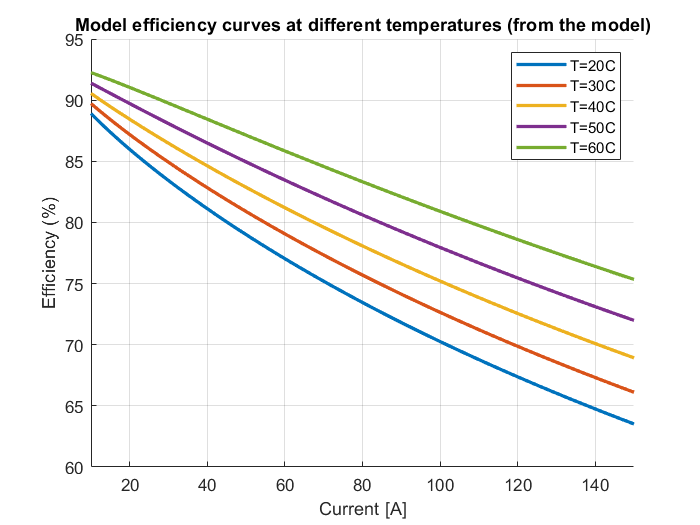

effig = figure;
voltfig = figure;
hold on
for i = 20:10:60
    temp = (KtoC+i);
    voltages = [];
    efficiencies = [];
    for k = minI:maxI
        voltages(k-minI+1) = fittedmodel(current(k-minI+1), temp);
        efficiencies(k-minI+1) = V0_hydrogen./voltages(k-minI+1);
    end
    set(0, 'CurrentFigure', effig)
    hold on
    plot(current,efficiencies.*100,"DisplayName","T=" + num2str(temp(1)-KtoC)+"C","LineWidth",2)
    hold off
    set(0, 'CurrentFigure', voltfig)
    hold on
    plot(current,voltages.*ncell,"DisplayName","T=" + num2str(temp(1)-KtoC)+"C","LineWidth",2)
    hold off
end

set(0, 'CurrentFigure', effig)
xlim([minI,maxI])
legend
grid on
xlabel("Current [A]")
ylabel("Efficiency (%)")
title("Model efficiency curves at different temperatures (from the model)")

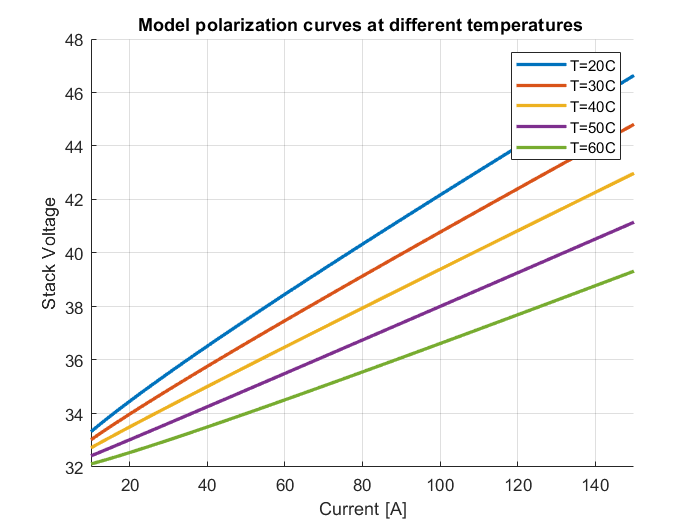


set(0, 'CurrentFigure', voltfig)
xlim([minI,maxI])
legend
grid on
xlabel("Current [A]")
ylabel("Stack Voltage")
title("Model polarization curves at different temperatures ")

## Efficiency analysis for model predictive control (Using the given power)

#### Define working parameters to plot

minT = 10+KtoC;
maxT = 60+KtoC;
minI = 10;
maxI = 140;
Twork = 50;

#### Create a grid with possible working temp. and working current values

[currents, temperatures] = meshgrid(minI:0.01:maxI,minT:0.01:maxT);
voltages = fittedmodel(currents,temperatures).*ncell;
powers = voltages.*currents;
efficiencies = V0_hydrogen./(ncell.*voltages);

#### Plot the efficiency curves

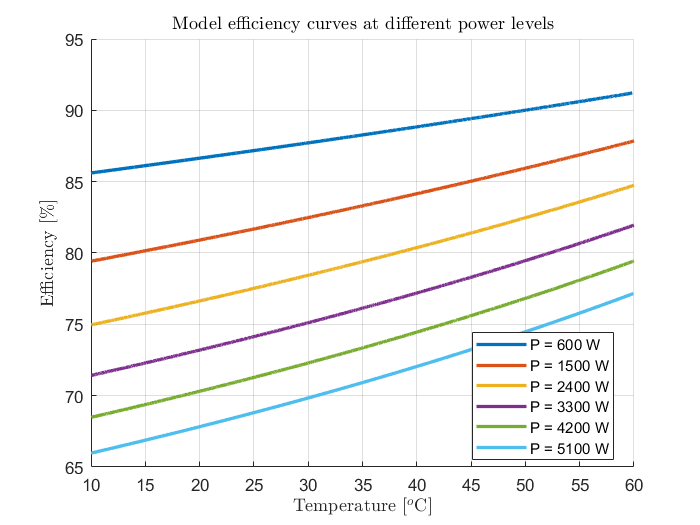

figure;
for pow = 600:900:5500
    slice = epsilon_equal(powers,pow,0.1);
    hold on
    tempvect = temperatures(slice);
    effvect = V0_hydrogen./voltages(slice).*ncell;
    plot(tempvect-KtoC,effvect.*100,"DisplayName","P = "+ num2str(pow) + " W","LineWidth",2);
    hold off
end
legend("location","best")
grid on
xlabel("Temperature [$^o$C]","Interpreter","latex")
ylabel("Efficiency [\%]","Interpreter","latex")
title("Model efficiency curves at different power levels","Interpreter","latex")

#### Plot the polarization curves

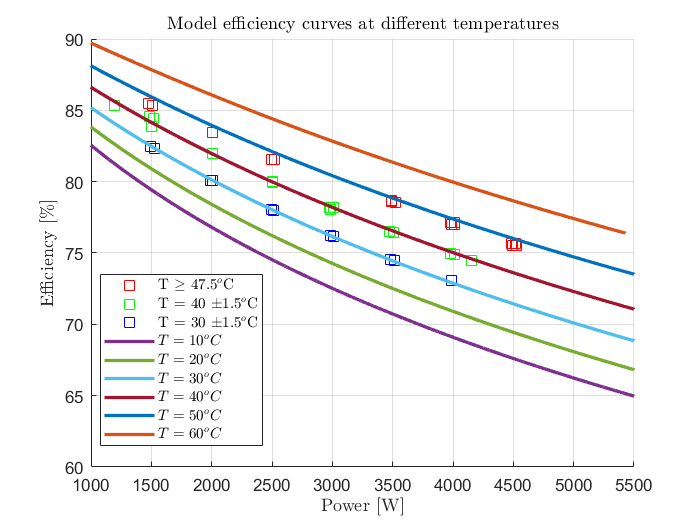

figure;
hold on
plot(cleandata.P(tempslice50),ncell.*V0_hydrogen./cleandata.U_stack(tempslice50).*100,"rs","MarkerSize",8,"DisplayName","T $\geq$ 47.5$^o$C")
plot(cleandata.P(tempslice40),ncell.*V0_hydrogen./cleandata.U_stack(tempslice40).*100,"gs","MarkerSize",8,"DisplayName","T = 40 $\pm 1.5 ^o$C")
plot(cleandata.P(tempslice30),ncell.*V0_hydrogen./cleandata.U_stack(tempslice30).*100,"bs","MarkerSize",8,"DisplayName","T = 30 $\pm 1.5 ^o$C")
hold off
for temp = minT:10:maxT
    slice = epsilon_equal(temperatures,temp,0.05);
    hold on
    powvect = powers(slice);
    effvect = EH2./(2.*voltages(slice).*F).*ncell;
    plot(powvect,effvect.*100,"DisplayName","$T = "+ num2str(temp-KtoC) + "^o C$","LineWidth",2);
    hold off
end
legend("location","best","Interpreter","latex")
grid on
xlabel("Power [W]","Interpreter","latex")
xlim([1000 5500])
ylabel("Efficiency [\%]","Interpreter","latex")
title("Model efficiency curves at different temperatures","Interpreter","latex")

#### Plot hydrogen generation curves

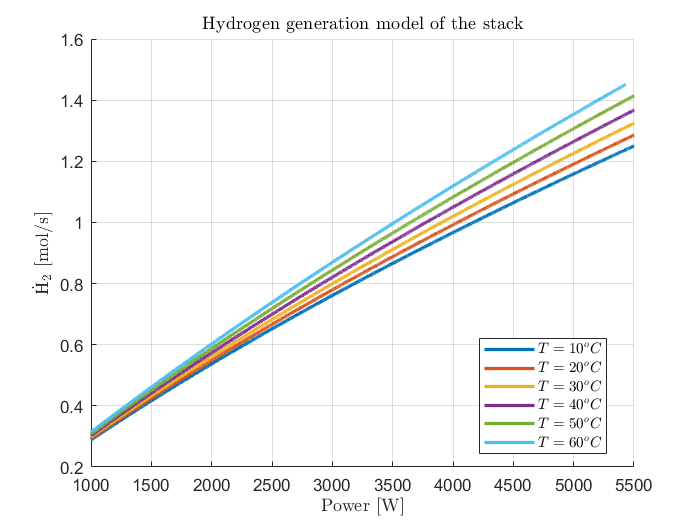

figure;
for temp = minT:10:maxT
    slice = epsilon_equal(temperatures,temp,0.05);
    hold on
    powvect = powers(slice);
    Hflow = ncell.*currents(slice)./(2*F);
    plot(powvect,Hflow.*100,"DisplayName","$T = "+ num2str(temp-KtoC) + "^o C$","LineWidth",2);
    hold off
end
legend("location","best","Interpreter","latex")
grid on
xlabel("Power [W]","Interpreter","latex")
xlim([1000 5500])
ylabel("$\dot{\mathrm{H}}_2$ [mol/s]","Interpreter","latex")
title("Hydrogen generation model of the stack","Interpreter","latex")

#### Plot tank filling curves in time

The equation below is used:


$$p_{H_2}(P,t) = \frac{n\cdot I_{@T^oC}(P)\cdot R \cdot T_{tank}}{2\cdot F \cdot V_{tank}}\cdot t$$


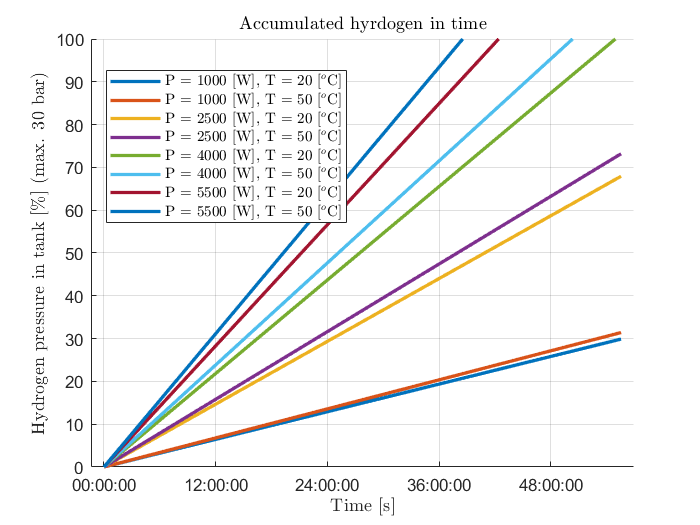

figure;
temp = Twork;
time = 0:10000:200000;
for pow = 1000:1500:5500
    for temp = 20:30:50    
        slice = epsilon_equal(temperatures,temp + KtoC,0);
        pow_vect = powers(slice);
        I_vect = currents(slice);
        I_operating = interp1(pow_vect,I_vect,pow);
        hold on
        tankP = (ncell*I_operating*R*(Tamb+KtoC).*time./(2*F*Vtank))./bar_to_Pa;
        plot(seconds(time),tankP./30.*100,'DurationTickFormat','hh:mm:ss',"DisplayName","P = "+ num2str(pow) + " [W], T = " + num2str(temp) + " [$^o$C]","LineWidth",2);
        hold off
    end
end
legend("location","best","Interpreter","latex")
grid on
xlabel("Time [s]","Interpreter","latex")
ylabel("Hydrogen pressure in tank [\%] (max. 30 bar)","Interpreter","latex")
ylim([0, 100])
title("Accumulated hyrdogen in time","Interpreter","latex")

Utility function to choose data samples close to a given value.

function bool = epsilon_equal(y,y0,epsilon)
    bool = abs(y-y0)<=epsilon;
end